# Speech Command Recognition Using Deep Learning

This example shows how to train a simple deep learning model that detects the presence of speech commands in audio. The example uses the Speech Commands Dataset [1] to train a convolutional neural network to recognize a given set of commands.

To run the example, you must first download the data set. If you do not want to download the data set or train the network, then you can load a pretrained network by opening this example in MATLAB® and typing `load('commandNet.mat')` at the command line. After loading the network, go directly to the last section of this example, *Detect Commands Using Streaming Audio from Microphone*.

## Load Speech Commands Data Set

Set `datafolder` to the location of the data. Use `audioDatastore` to create a datastore that contains the file names and the corresponding labels. Use the folder names as the label source. Specify the read method to read the entire audio file. Create a copy of the datastore for later use.

clear
PathToDatabase = './Dataset/Train/';
datafolder = PathToDatabase;
ads = audioDatastore(datafolder, ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','foldernames')

ads =   audioDatastore with properties:

                       Files: {
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/11/1_1.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/11/1_10.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/11/1_11.wav'
                               ... and 5654 more
                              }
                      Labels: [11; 11; 11 ... and 5654 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'


ads0 = copy(ads);

PathToDatabaseTest = './Dataset/Test/';
datafolderTest = PathToDatabaseTest;
adsTest = audioDatastore(datafolderTest, ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','foldernames')

adsTest =   audioDatastore with properties:

                       Files: {
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Test/11/1_1.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Test/11/1_10.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Test/11/1_11.wav'
                               ... and 412 more
                              }
                      Labels: [11; 11; 11 ... and 412 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'


adsTest0 = copy(adsTest);

## Choose Words to Recognize

Specify the words that you want your model to recognize as commands. Label all words that are not commands as `unknown`. Labeling words that are not commands as `unknown` creates a group of words that approximates the distribution of all words other than the commands. The network uses this group to learn the difference between commands and all other words.

To reduce the class imbalance between the known and unknown words and speed up processing, only include a fraction `includeFraction` of the unknown words in the training set. Do not include the longer files with background noise in the training set yet. Background noise will be added in a separate step later.

Use `subset(ads,indices)` to create a datastore that contains only the files and labels indexed by `indices`. Reduce the datastore `ads` so that it contains only the commands and the subset of unknown words. Count the number of examples belonging to each class.

%commands = categorical(["21","22","23","24"]);
commands = categorical(["LR","UD"]);

isLR = ismember(ads.Labels,categorical(["21","22"]));
ads.Labels(isLR) = categorical("LR");
isUD = ismember(ads.Labels,categorical(["23","24"]));
ads.Labels(isUD) = categorical("UD");


isCommand = ismember(ads.Labels,[commands,"BG"]);
isUnknown = ~ismember(ads.Labels,[commands,"BG"]);

%ads.Labels(isUnknown) = categorical("BG");

ads = subset(ads,isCommand)%|isUnknown);

ads =   audioDatastore with properties:

                       Files: {
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/21/1_1.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/21/1_10.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/21/1_11.wav'
                               ... and 2698 more
                              }
                      Labels: [LR; LR; LR ... and 2698 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'


countEachLabel(ads)

ans = 3×2 table
    Label    Count
    _____    _____

     BG      1800 
     LR       450 
     UD       451 



isLR = ismember(adsTest.Labels,categorical(["21","22"]));
adsTest.Labels(isLR) = categorical("LR");
isUD = ismember(adsTest.Labels,categorical(["23","24"]));
adsTest.Labels(isUD) = categorical("UD");

isCommand_test = ismember(adsTest.Labels,[commands,"BG"]);
isUnknown_test = ~ismember(adsTest.Labels,[commands,"BG"]);

%adsTest.Labels(isUnknown_test) = categorical("BG");

adsTest = subset(adsTest,isCommand_test)%|isUnknown_test);

adsTest =   audioDatastore with properties:

                       Files: {
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Test/21/1_1.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Test/21/1_10.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Test/21/1_11.wav'
                               ... and 172 more
                              }
                      Labels: [LR; LR; LR ... and 172 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'


countEachLabel(adsTest)

ans = 3×2 table
    Label    Count
    _____    _____

     BG       100 
     LR        37 
     UD        38 


## Split Data into Training, Validation, and Test Sets

The data set folder contains text files, which list the audio files to be used as the validation and test sets. These predefined validation and test sets do not contain utterances of the same word by the same person, so it is better to use these predefined sets than to select a random subset of the whole data set. Use the supporting function [`splitData`](matlab:edit(fullfile(matlabroot,'examples','deeplearning_shared','main','splitData.m'))) to split the datastore into training, validation, and test sets based on the list of validation and test files located in the data set folder.

Because this example trains a single network, it only uses the validation set and not the test set to evaluate the trained model. If you train many networks and choose the network with the highest validation accuracy as your final network, then you can use the test set to evaluate the final network.

[adsTrain,adsValidation] = splitData(ads,datafolder)

adsTrain =   audioDatastore with properties:

                       Files: {
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/21/1_1.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/21/1_10.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/21/1_12.wav'
                               ... and 2261 more
                              }
                      Labels: [LR; LR; LR ... and 2261 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'


adsValidation =   audioDatastore with properties:

                       Files: {
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/21/1_11.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/21/1_14.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/21/1_19.wav'
                               ... and 434 more
                              }
                      Labels: [LR; LR; LR ... and 434 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'


## Compute Speech Spectrograms

To prepare the data for efficient training of a convolutional neural network, convert the speech waveforms to log-mel spectrograms.

Define the parameters of the spectrogram calculation. `segmentDuration` is the duration of each speech clip (in seconds). `frameDuration` is the duration of each frame for spectrogram calculation. `hopDuration` is the time step between each column of the spectrogram. `numBands` is the number of log-mel filters and equals the height of each spectrogram.

segmentDuration = 700/256;
frameDuration = 150/256;
hopDuration = 15/256;
numBands = 15;
epsil = 1e-6;

Compute the spectrograms for the training, validation, and test sets by using the supporting function [`speechSpectrograms`](matlab:edit(fullfile(matlabroot,'examples','deeplearning_shared','main','speechSpectrograms.m'))). The `speechSpectrograms` function uses `designAuditoryFilterBank` for the log-mel spectrogram calculations. To obtain data with a smoother distribution, take the logarithm of the spectrograms using a small offset `epsil`.



adsTrain.reset();
adsTest.reset();
adsValidation.reset();
%error('Uncomment this to generate spects again. Otherwise load values using the line below:')
%load('DS.mat', 'XTrain', 'XTest', 'XValidation', 'YTrain','YTest','YValidation');
XTrain = speechSpectrograms(adsTrain,segmentDuration,frameDuration,hopDuration,numBands);

Computing speech spectrograms...
Processed 100 files out of 2269
Processed 200 files out of 2269
Processed 300 files out of 2269
Processed 400 files out of 2269
Processed 500 files out of 2269
Processed 600 files out of 2269
Processed 700 files out of 2269
Processed 800 files out of 2269
Processed 900 files out of 2269
Processed 1000 files out of 2269
Processed 1100 files out of 2269
Processed 1200 files out of 2269
Processed 1300 files out of 2269
Processed 1400 files out of 2269
Processed 1500 files out of 2269
Processed 1600 files out of 2269
Processed 1700 files out of 2269
Processed 1800 files out of 2269
Processed 1900 files out of 2269
Processed 2000 files out of 2269
Processed 2100 files out of 2269
Processed 2200 files out of 2269
...done


XTrain = log10(XTrain + epsil);

XValidation = speechSpectrograms(adsValidation,segmentDuration,frameDuration,hopDuration,numBands);

Computing speech spectrograms...
Processed 100 files out of 432
Processed 200 files out of 432
Processed 300 files out of 432
Processed 400 files out of 432
...done


XValidation = log10(XValidation + epsil);

XTest = speechSpectrograms(adsTest,segmentDuration,frameDuration,hopDuration,numBands);

Computing speech spectrograms...
Processed 100 files out of 175
...done


XTest = log10(XTest + epsil);

YTrain = adsTrain.Labels;
YValidation = adsValidation.Labels;
YTest = adsTest.Labels;

YTrain = removecats(YTrain)

YTrain = 2269×1 categorical array
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 


YValidation = removecats(YValidation)

YValidation = 432×1 categorical array
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 


YTest = removecats(YTest)

YTest = 175×1 categorical array
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 
     LR 



XTest(:,:,5,:)=[];
XValidation(:,:,5,:)=[];
XTrain(:,:,5,:)=[];

save('DS.mat', 'XTrain', 'XTest', 'XValidation', 'YTrain','YTest','YValidation');

## Visualize Data

Plot the waveforms and spectrograms of a training example. 

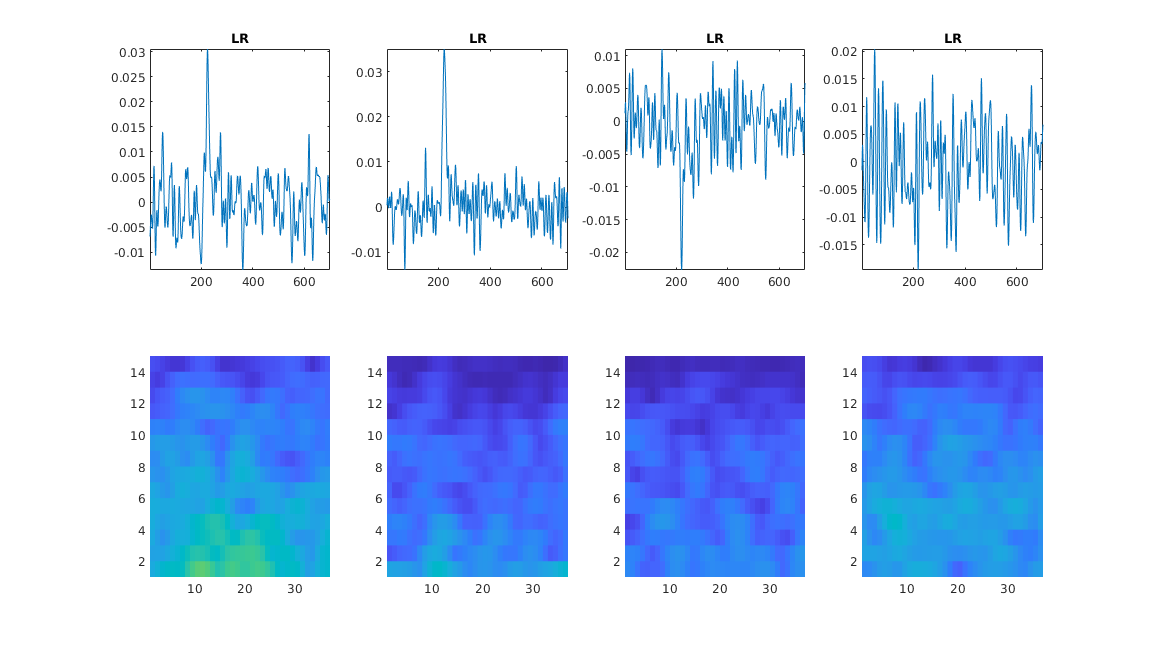

load('DS.mat', 'XTrain', 'XTest', 'XValidation', 'YTrain','YTest','YValidation');
specMin = min(XValidation(:));
specMax = max(XValidation(:));
idx = 11;%randperm(size(XValidation,4),1);
figure('Units','normalized','Position',[0.2 0.2 0.6 0.6]);
for i = 1:4
    [x,~] = audioread(adsValidation.Files{idx(1)});
    subplot(2,4,i)
    plot(x(:,i))
    axis tight
    title(string(adsValidation.Labels(idx(1))))
    
    subplot(2,4,i+4)
    spect = XValidation(:,:,i,idx(1));
    pcolor(spect)
    caxis([specMin specMax])
    shading flat
    
end

Training neural networks is easiest when the inputs to the network have a reasonably smooth distribution and are normalized. To check that the data distribution is smooth, plot a histogram of the pixel values of the training data.

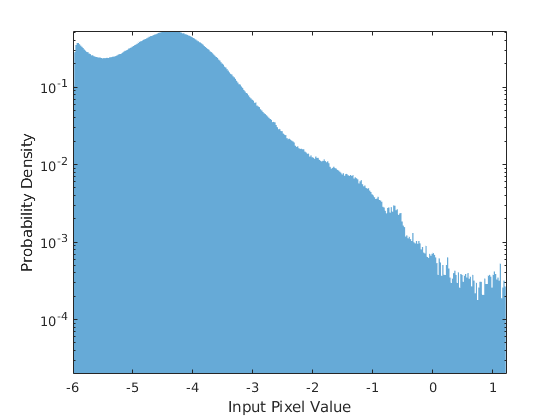

figure
histogram(XTrain,'EdgeColor','none','Normalization','pdf')
axis tight
ax = gca;
ax.YScale = 'log';
xlabel("Input Pixel Value")
ylabel("Probability Density")

Plot the distribution of the different class labels in the training and validation sets. The test set has a very similar distribution to the validation set.

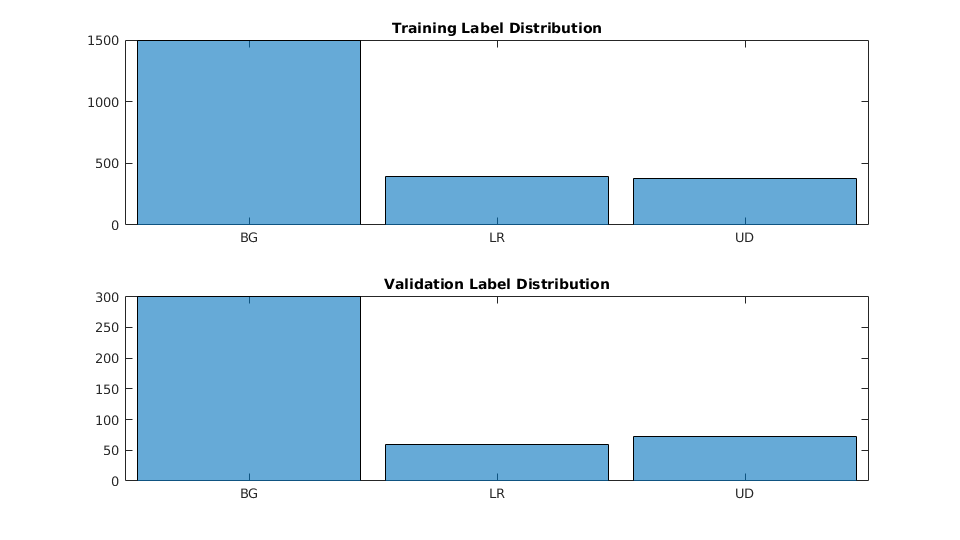

figure('Units','normalized','Position',[0.2 0.2 0.5 0.5]);
subplot(2,1,1)
histogram(YTrain)
title("Training Label Distribution")
subplot(2,1,2)
histogram(YValidation)
title("Validation Label Distribution")

## Add Data Augmentation

Create an augmented image datastore for automatic augmentation and resizing of the spectrograms. Translate the spectrogram randomly up to 10 frames (100 ms) forwards or backwards in time, and scale the spectrograms along the time axis up or down by 20 percent. Augmenting the data can increase the effective size of the training data and help prevent the network from overfitting. The augmented image datastore creates augmented images in real time during training and inputs them to the network. No augmented spectrograms are saved in memory.

sz = size(XTrain);
specSize = sz(1:2);
imageSize = [specSize 4];
augmenter = imageDataAugmenter( ...
    'RandXTranslation',[-5 5], ...
    'RandXScale',[0.9 1.1], ...
    'FillValue',log10(epsil));
augimdsTrain = augmentedImageDatastore(imageSize,XTrain,YTrain, ...
    'DataAugmentation',augmenter)

augimdsTrain =   augmentedImageDatastore with properties:

         NumObservations: 2269
           MiniBatchSize: 128
        DataAugmentation: [1×1 imageDataAugmenter]
      ColorPreprocessing: 'none'
              OutputSize: [15 37]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


## Define Neural Network Architecture

Create a simple network architecture as an array of layers. Use convolutional and batch normalization layers, and downsample the feature maps "spatially" (that is, in time and frequency) using max pooling layers. Add a final max pooling layer that pools the input feature map globally over time. This enforces (approximate) time-translation invariance in the input spectrograms, allowing the network to perform the same classification independent of the exact position of the speech in time. Global pooling also significantly reduces the number of parameters in the final fully connected layer. To reduce the possibility of the network memorizing specific features of the training data, add a small amount of dropout to the input to the last fully connected layer.

The network is small, as it has only five convolutional layers with few filters. `numF` controls the number of filters in the convolutional layers. To increase the accuracy of the network, try increasing the network depth by adding identical blocks of convolutional, batch normalization, and ReLU layers. You can also try increasing the number of convolutional filters by increasing `numF`.

Use a weighted cross entropy classification loss. [`weightedClassificationLayer(classWeights)`](matlab:edit(fullfile(matlabroot,'examples','deeplearning_shared','main','weightedClassificationLayer.m'))) creates a custom classification layer that calculates the cross entropy loss with observations weighted by `classWeights`. Specify the class weights in the same order as the classes appear in `categories(YTrain)`. To give each class equal total weight in the loss, use class weights that are inversely proportional to the number of training examples in each class. When using the Adam optimizer to train the network, the training algorithm is independent of the overall normalization of the class weights.

classWeights = 1./countcats(YTrain);
classWeights = classWeights'/mean(classWeights)

classWeights =     0.3413    1.3086    1.3500


%classWeights(1) = classWeights(1) * 0.01;
numClasses = numel(categories(YTrain));

timePoolSize = ceil(imageSize(2)/2);
dropoutProb = 0.1;
numF = 40;
layers = [
    imageInputLayer(imageSize)
    
    convolution2dLayer(1,10,'Padding','same')
    %batchNormalizationLayer
    reluLayer
    
    convolution2dLayer(3,numF,'Padding','same')
    %batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2,'Padding','same')
    
    convolution2dLayer(3,numF,'Padding','same')
    %batchNormalizationLayer
    reluLayer
    
    %maxPooling2dLayer(3,'Stride',2,'Padding','same')
    
    convolution2dLayer(3,numF*2,'Padding','same')
    %batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2,'Padding','same')
    
    %convolution2dLayer(3,2*numF,'Padding','same')
    %batchNormalizationLayer
    %reluLayer
    
    %averagePooling2dLayer(3,'Stride',2,'Padding','same')
    
    %convolution2dLayer(3,4*numF,'Padding','same')
    %batchNormalizationLayer
    %reluLayer
    %convolution2dLayer(1,4*numF,'Padding','same')
    %batchNormalizationLayer
    %reluLayer
     
    %averagePooling2dLayer([1 timePoolSize])
    
    dropoutLayer(dropoutProb)
    fullyConnectedLayer(10)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    weightedClassificationLayer(classWeights)];

## Train Network

Specify the training options. Use the Adam optimizer with a mini-batch size of 128. Train for 25 epochs and reduce the learning rate by a factor of 10 after 20 epochs.

miniBatchSize = 30;
validationFrequency = floor(numel(YTrain)/miniBatchSize)*2;
options = trainingOptions('adam', ...
    'InitialLearnRate',3e-3, ...
    'MaxEpochs',50, ...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',true, ...
    'ValidationData',{XValidation,YValidation}, ...
    'ValidationFrequency',validationFrequency, ...
    'LearnRateSchedule','piecewise', ...
    'ValidationPatience',4, ...
    'LearnRateDropFactor',0.1, ...
    'LearnRateDropPeriod',30);

Train the network. If you do not have a GPU, then training the network can take time. To load a pretrained network instead of training a network from scratch, set `doTraining` to `false`.

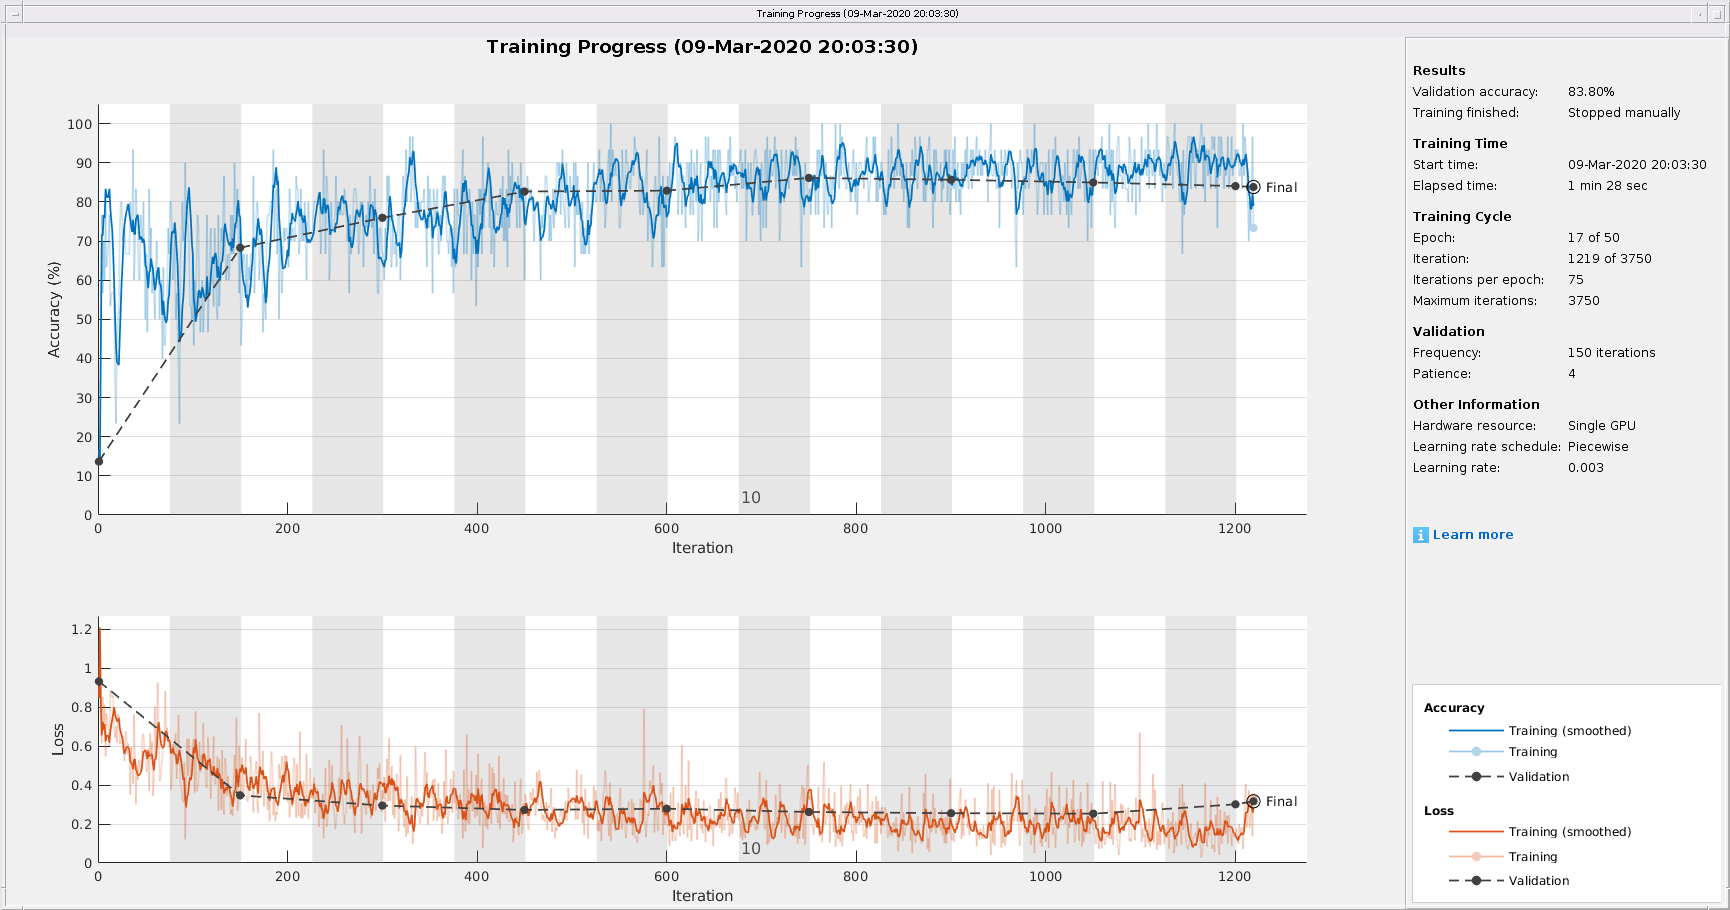

Training on single GPU.

doTraining = true;
if doTraining
    trainedNet = trainNetwork(augimdsTrain,layers,options); 
    save('commandNet.mat','trainedNet');
else
    load('commandNet.mat','trainedNet');
end

## Evaluate Trained Network

Calculate the final accuracy of the network on the training set (without data augmentation) and validation set. The network is very accurate on this data set. However, the training, validation, and test data all have similar distributions that do not necessarily reflect real-world environments. This limitation particularly applies to the `unknown` category, which contains utterances of only a small number of words.


YValPred = classify(trainedNet,XValidation);
validationError = mean(YValPred ~= YValidation);
YTrainPred = classify(trainedNet,XTrain);
trainError = mean(YTrainPred ~= YTrain);
disp("Training error: " + trainError*100 + "%")

Training error: 10.8859%


disp("Validation error: " + validationError*100 + "%")

Validation error: 16.2037%



YTestPred = classify(trainedNet,XTest);
testError = mean(YTestPred ~= YTest);
disp("Test error: " + testError*100 + "%")

Test error: 29.1429%


Plot the confusion matrix. Display the precision and recall for each class by using column and row summaries. Sort the classes of the confusion matrix. The largest confusion is between unknown words and commands, *up* and *off*, *down* and *no*, and *go* and *no*.

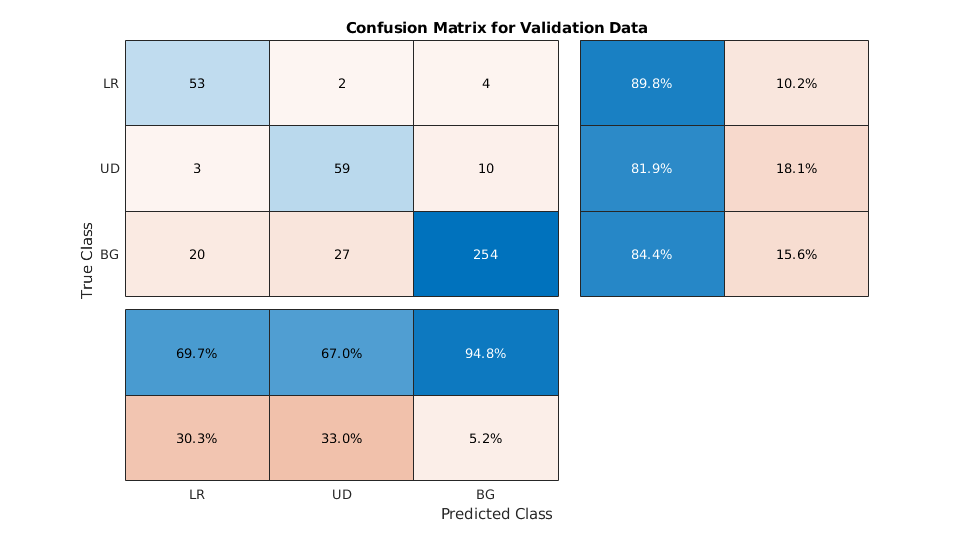

figure('Units','normalized','Position',[0.2 0.2 0.5 0.5]);
cm = confusionchart(YValidation,YValPred);
cm.Title = 'Confusion Matrix for Validation Data';
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
sortClasses(cm, [commands,"BG"])

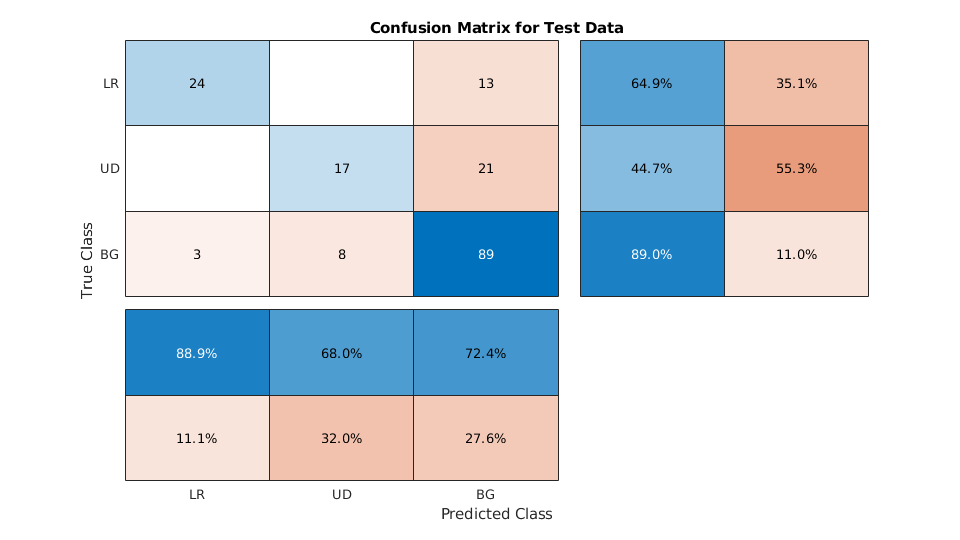


figure('Units','normalized','Position',[0.2 0.2 0.5 0.5]);
cm = confusionchart(YTest,YTestPred);
cm.Title = 'Confusion Matrix for Test Data';
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
sortClasses(cm, [commands,"BG"])

When working on applications with constrained hardware resources such as mobile applications, consider the limitations on available memory and computational resources. Compute the total size of the network in kilobytes and test its prediction speed when using a CPU. The prediction time is the time for classifying a single input image. If you input multiple images to the network, these can be classified simultaneously, leading to shorter prediction times per image. When classifying streaming audio, however, the single-image prediction time is the most relevant.

info = whos('trainedNet');
disp("Network size: " + info.bytes/1024 + " kB")

for i=1:100
    x = randn(imageSize);
    tic
    [YPredicted,probs] = classify(trainedNet,x,"ExecutionEnvironment",'cpu');
    time(i) = toc;
end
disp("Single-image prediction time on CPU: " + mean(time(11:end))*1000 + " ms")

## Detect Commands Using Streaming Audio from Microphone

Test your newly trained command detection network on streaming audio from your microphone. If you have not trained a network, then type `load('commandNet.mat')` at the command line to load a pretrained network and the parameters required to classify live, streaming audio. Try saying one of the commands, for example, *yes*, *no*, or *stop*. Then, try saying one of the unknown words such as *Marvin*, *Sheila*, *bed*, *house*, *cat*, *bird*, or any number from zero to nine.

Specify the audio sampling rate and classification rate in Hz and create an audio device reader that can read audio from your microphone.

fs = 16e3;
classificationRate = 20;
audioIn = audioDeviceReader('SampleRate',fs, ...
    'SamplesPerFrame',floor(fs/classificationRate));

Specify parameters for the streaming spectrogram computations and initialize a buffer for the audio. Extract the classification labels of the network. Initialize buffers of half a second for the labels and classification probabilities of the streaming audio. Use these buffers to compare the classification results over a longer period of time and by that build 'agreement' over when a command is detected.

frameLength = floor(frameDuration*fs);
hopLength = floor(hopDuration*fs);
waveBuffer = zeros([fs,1]);

labels = trainedNet.Layers(end).Classes;
YBuffer(1:classificationRate/2) = categorical("background");
probBuffer = zeros([numel(labels),classificationRate/2]);

Create a figure and detect commands as long as the created figure exists. To stop the live detection, simply close the figure. 

h = figure('Units','normalized','Position',[0.2 0.1 0.6 0.8]);

filterBank = designAuditoryFilterBank(fs,'FrequencyScale','bark',...
    'FFTLength',512,...
    'NumBands',numBands,...
    'FrequencyRange',[50,7000]);

while ishandle(h)
    
    % Extract audio samples from the audio device and add the samples to
    % the buffer.
    x = audioIn();
    waveBuffer(1:end-numel(x)) = waveBuffer(numel(x)+1:end);
    waveBuffer(end-numel(x)+1:end) = x;
    
    % Compute the spectrogram of the latest audio samples.
    [~,~,~,spec] =  spectrogram(waveBuffer,hann(frameLength,'periodic'),frameLength - hopLength,512,'onesided');
    spec = filterBank * spec;
    spec = log10(spec + epsil);
    
    % Classify the current spectrogram, save the label to the label buffer,
    % and save the predicted probabilities to the probability buffer.
    [YPredicted,probs] = classify(trainedNet,spec,'ExecutionEnvironment','cpu');
    YBuffer(1:end-1)= YBuffer(2:end);
    YBuffer(end) = YPredicted;
    probBuffer(:,1:end-1) = probBuffer(:,2:end);
    probBuffer(:,end) = probs';
    
    % Plot the current waveform and spectrogram.
    subplot(2,1,1);
    plot(waveBuffer)
    axis tight
    ylim([-0.2,0.2])
    
    subplot(2,1,2)
    pcolor(spec)
    caxis([specMin+2 specMax])
    shading flat
    
    % Now do the actual command detection by performing a very simple
    % thresholding operation. Declare a detection and display it in the
    % figure title if all of the following hold:
    % 1) The most common label is not |background|.
    % 2) At least |countThreshold| of the latest frame labels agree.
    % 3) The maximum predicted probability of the predicted label is at
    % least |probThreshold|. Otherwise, do not declare a detection.
    [YMode,count] = mode(YBuffer);
    countThreshold = ceil(classificationRate*0.2);
    maxProb = max(probBuffer(labels == YMode,:));
    probThreshold = 0.7;
    subplot(2,1,1);
    if YMode == "background" || count<countThreshold || maxProb < probThreshold
        title(" ")
    else
        title(string(YMode),'FontSize',20)
    end
    
    drawnow
    
end

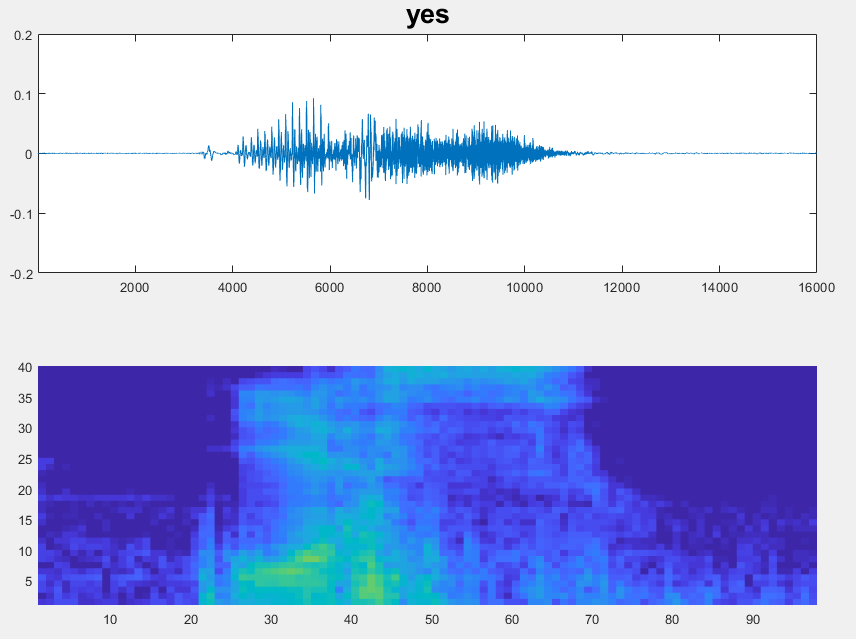

*Copyright 2018 The MathWorks, Inc.*